clear, clc, close all;

rng(1207); % For reproducibility
N = 100;

data = [
        randn(N, 2)*0.5  - ones(N, 2);
        randn(N, 2)*0.75 + ones(N, 2);
       ];
tic
[idx, C] = kmeans(data, 2);
toc

历时 0.004678 秒。


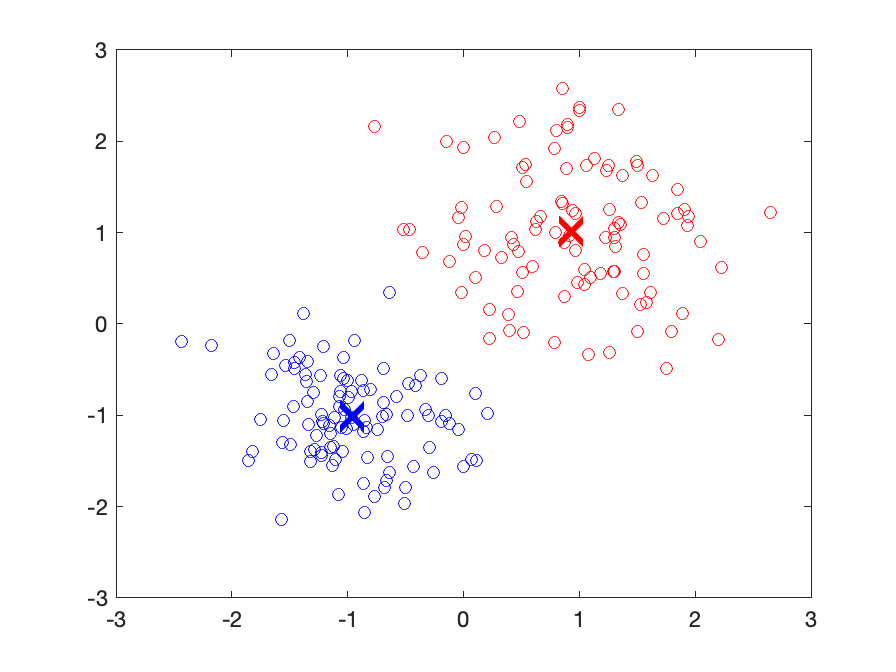

idx1 = find(idx == 1);
idx2 = find(idx == 2);
plotdata(data, idx1, idx2, C);

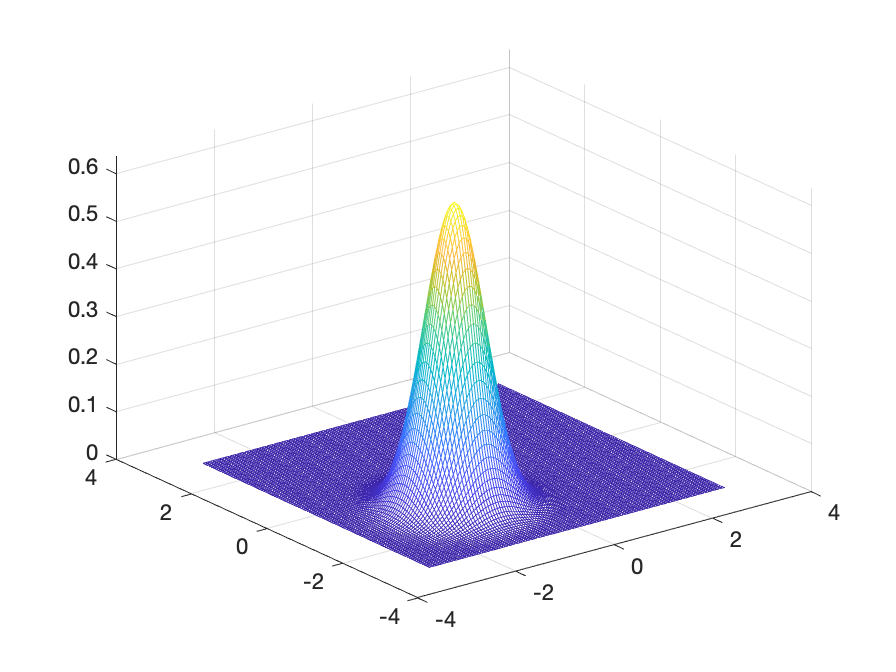


[X,Y] = meshgrid(-3:.05:3);
Z1 = gauss_2d(X, Y, C(1, 1), C(1, 2), 0.5);
Z2 = gauss_2d(X, Y, C(2, 1), C(2, 2), 0.75);
figure();
mesh(X,Y,Z1);

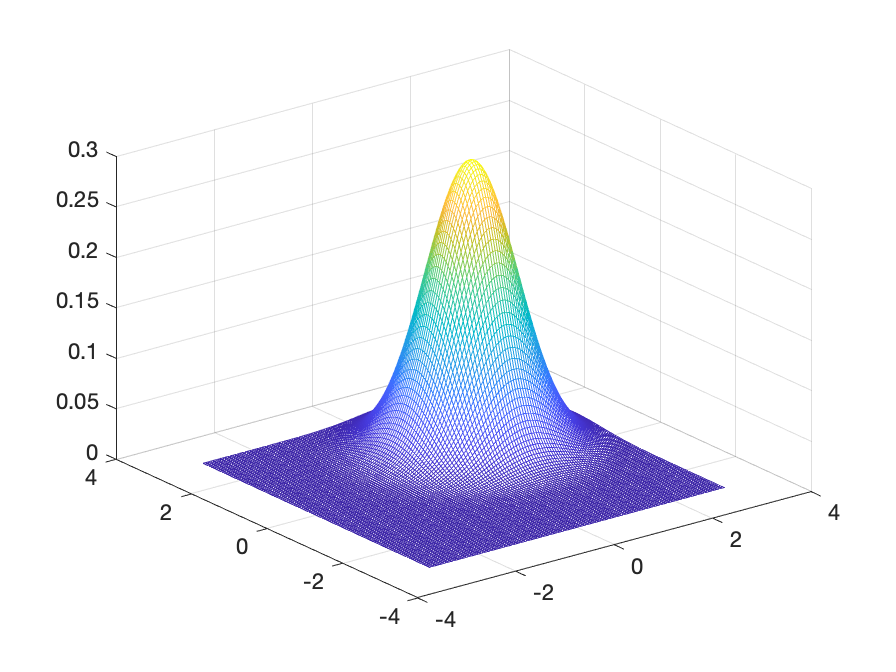

figure();
mesh(X,Y,Z2);

tic
[centers, U] = fcm(data, 2);

Iteration count = 1, obj. fcn = 313.800936
Iteration count = 2, obj. fcn = 262.787453
Iteration count = 3, obj. fcn = 250.376316
Iteration count = 4, obj. fcn = 184.246792
Iteration count = 5, obj. fcn = 125.177105
Iteration count = 6, obj. fcn = 120.989373
Iteration count = 7, obj. fcn = 120.914458
Iteration count = 8, obj. fcn = 120.912302
Iteration count = 9, obj. fcn = 120.912188
Iteration count = 10, obj. fcn = 120.912181


toc

历时 0.014620 秒。


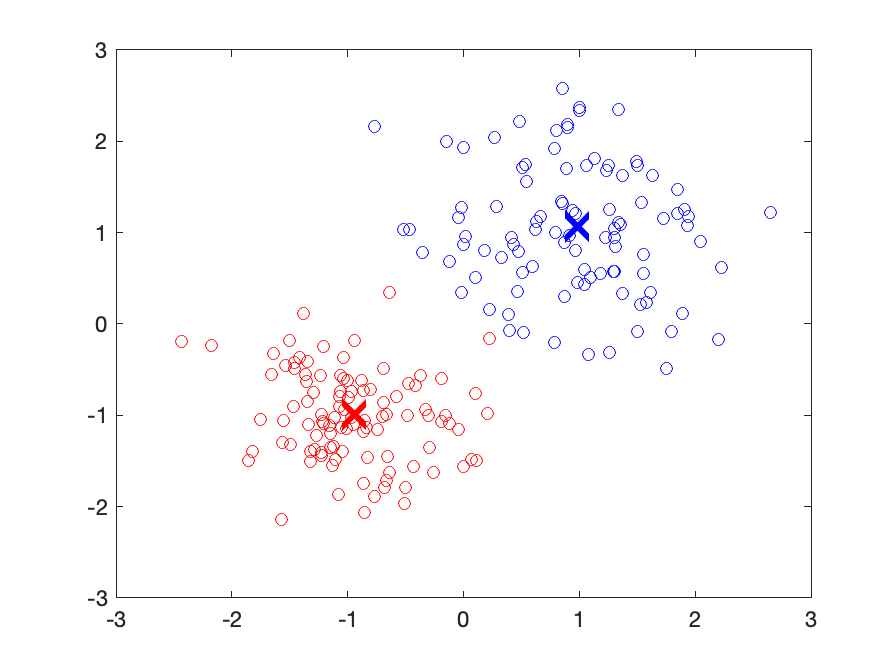

maxU = max(U);
index1 = find(U(1,:) == maxU);
index2 = find(U(2,:) == maxU);
figure();
plotdata(data, index1, index2, centers)

function plotdata(data, index1, index2, centers)
    plot(data(index1, 1),data(index1, 2),'ob');
    hold on;
    plot(data(index2, 1),data(index2, 2),'or');
    plot(centers(1, 1),centers(1, 2),...
        'xb','MarkerSize',15,'LineWidth',3);
    plot(centers(2, 1),centers(2, 2),...
        'xr','MarkerSize',15,'LineWidth',3);
    hold off;
end

function [z] = gauss_2d(x, y, x0, y0, sigma0)
    z = exp(-(...
        (x - x0) .^ 2 + (y - y0) .^ 2 ...
    ) ./ (...
        2 .* sigma0 .^ 2 ...
    )) ./ (2 .* pi .* sigma0 .^ 2);
end